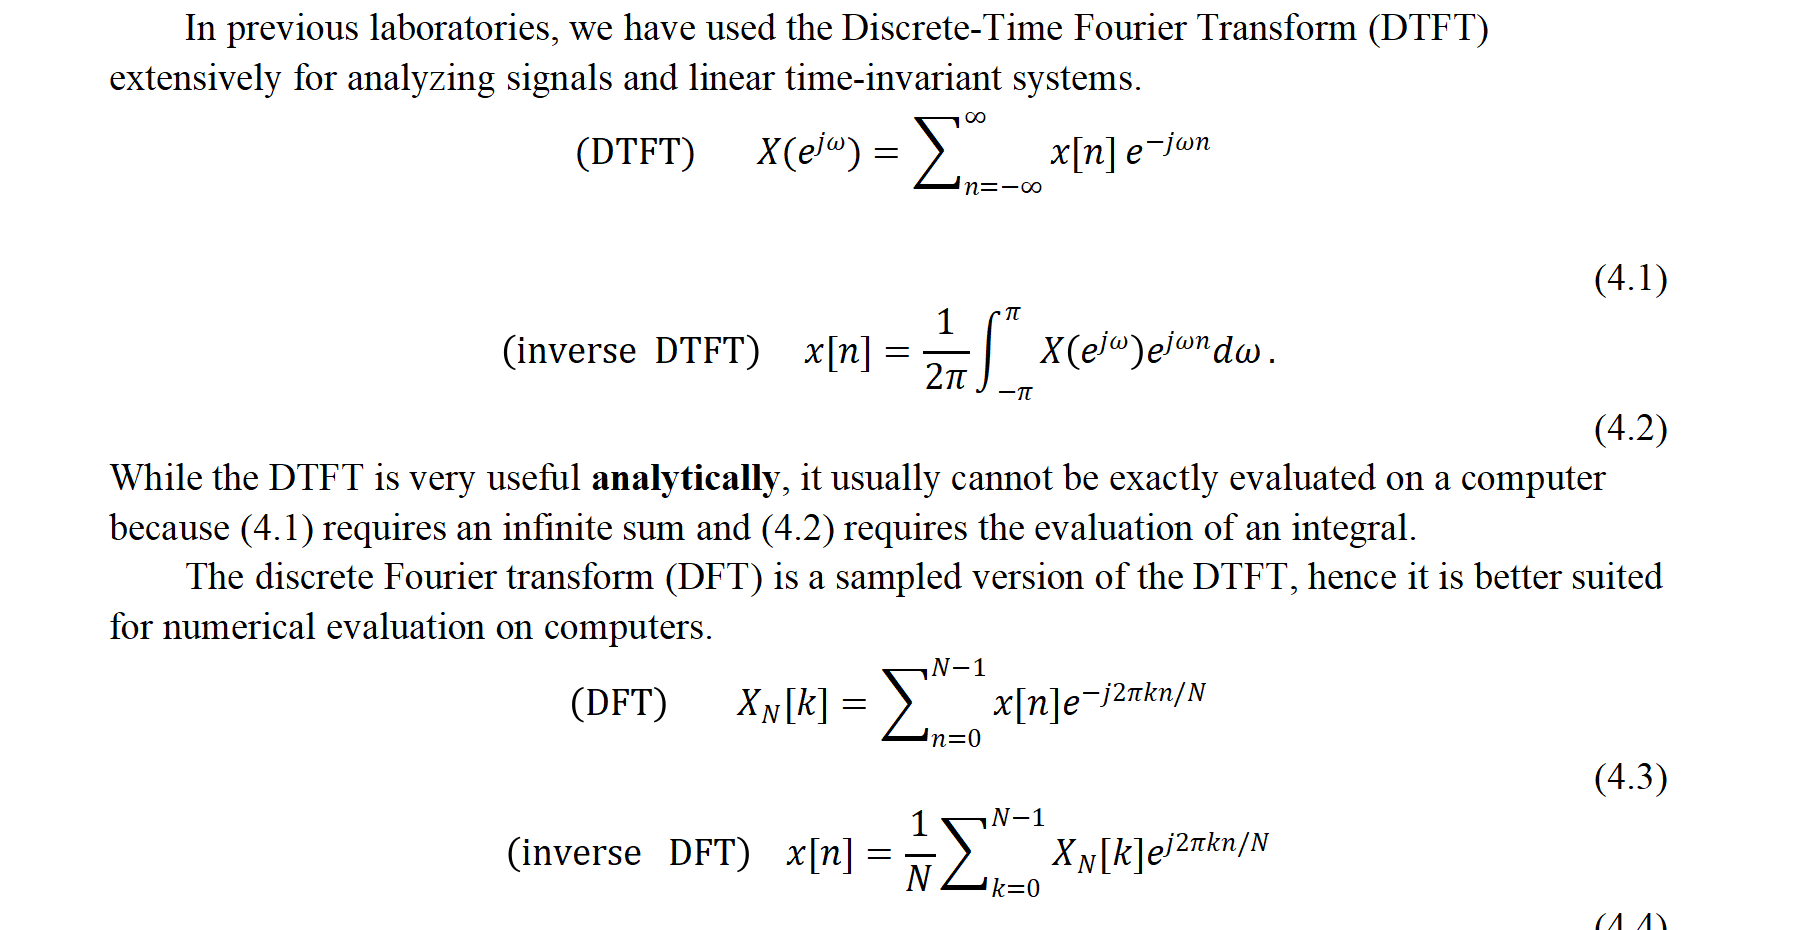

4.2 Deriving the DFT from the DTFT

**4****.2.3 Windowing Effects**

 plot the phase and magnitude of W(e^jw)

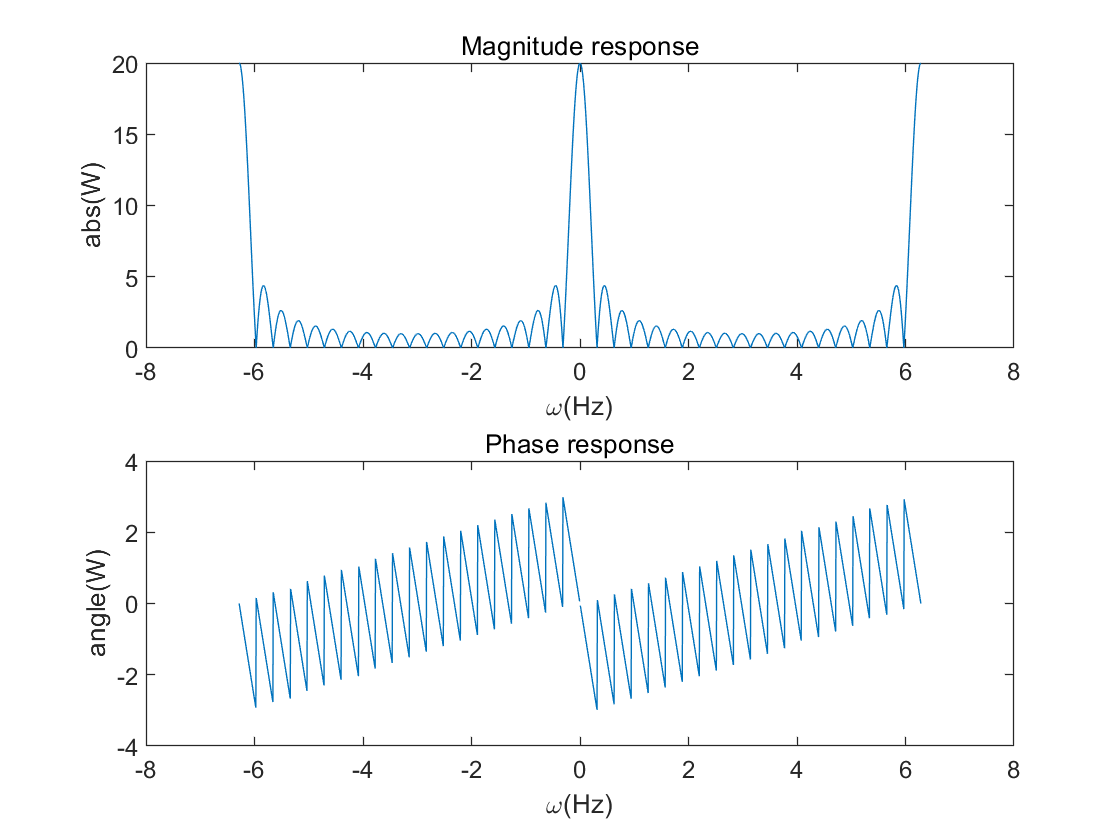

clear;
N=20;
w=-2*pi:2*pi/1000:2*pi;
W = (w~=0).*exp(-j*w*(N-1)/2).*sin(w*N/2)./(sin(w/2))+(w == 0)*N;
figure
subplot(2,1,1),plot(w,abs(W)),xlabel('\omega(Hz)'),ylabel('abs(W)'),title('Magnitude response');
subplot(2,1,2),plot(w,unwrap(angle(W))),xlabel('\omega(Hz)'),ylabel('angle(W)'),title('Phase response');

Truncate the signal X[n]  using a window of size N=20 and then use DTFT.m to compute Xtr(e^jw).

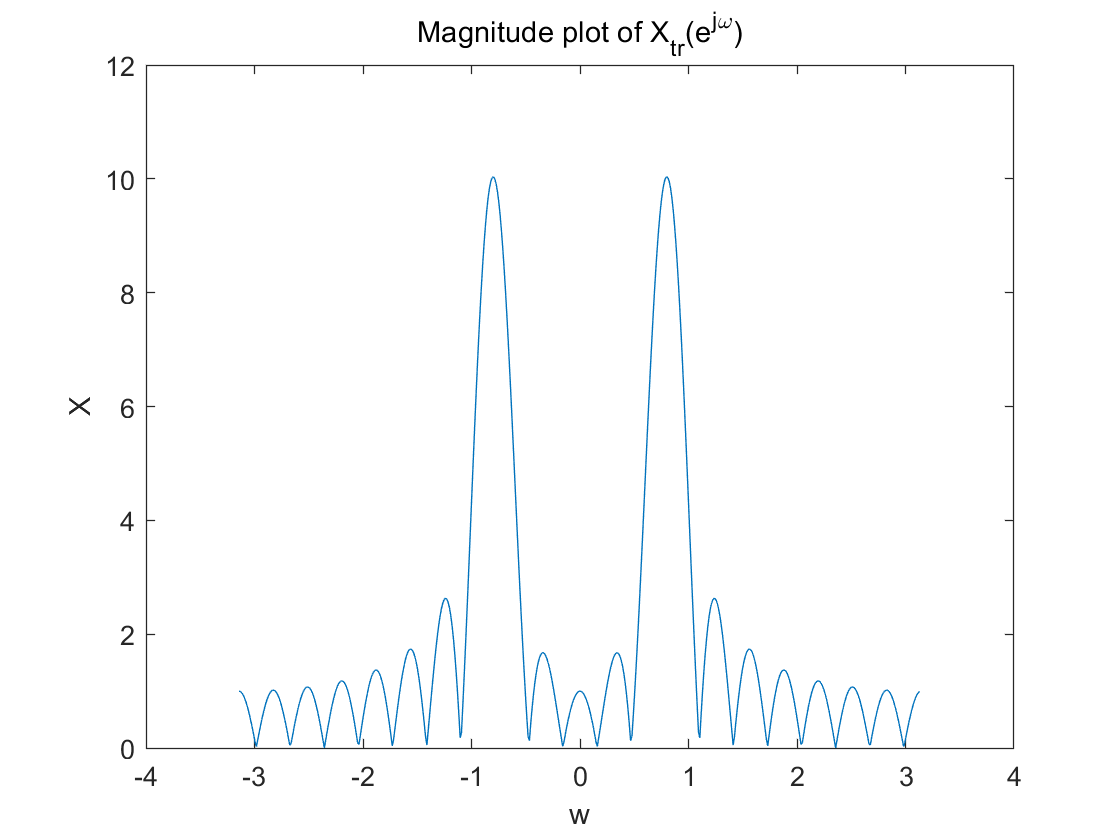

clear;
% Truncate the signal
n=0:19;
x=cos(pi/4*n);
[X,w]=DTFT(x,512);
figure
plot(w,abs(X)),xlabel('w'),ylabel('X'),title('Magnitude plot of X_{tr}(e^{j\omega})');

two time-shiftings of a sinc waves

**4.3 The Discrete Fourier Transform**

**4****.3.1 Computing the DFT**

N = 10;
n=[0:9]%????????

n =      0     1     2     3     4     5     6     7     8     9


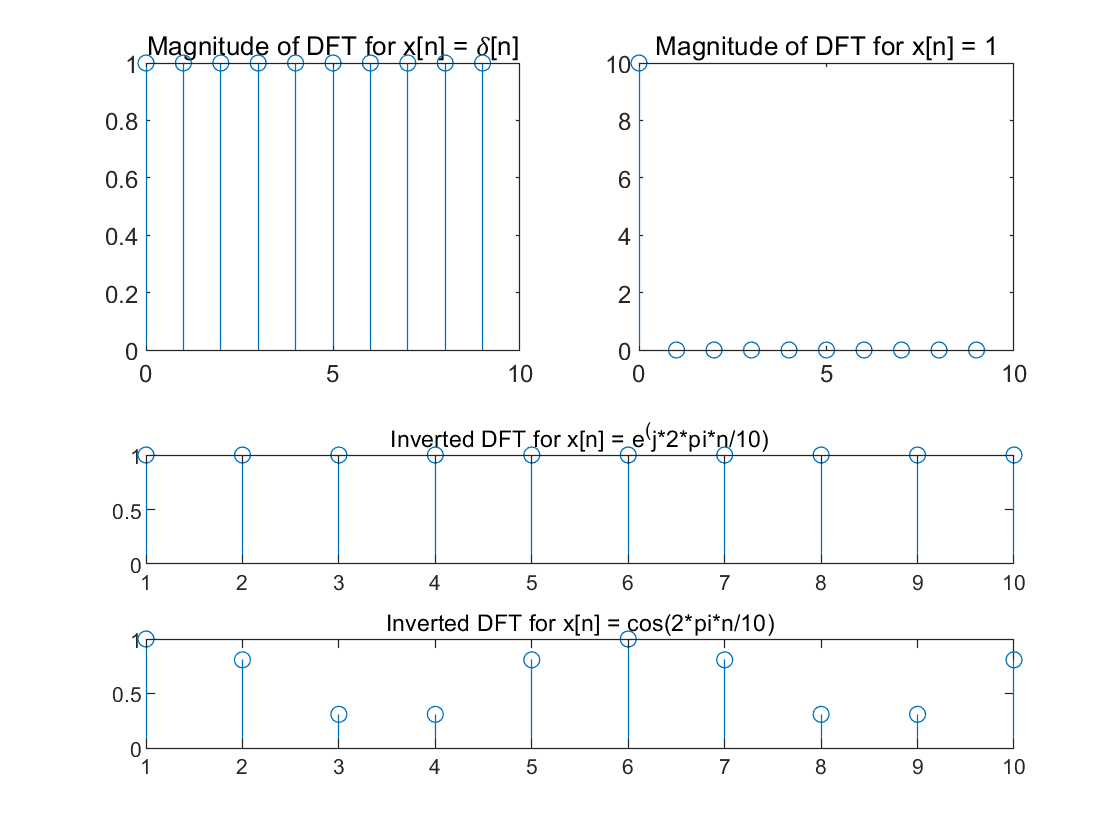

%：x[n] = 𝛿[n]
x1 = [1 zeros(1, N-1)];
X1 = DFTsum(x1);
subplot(2, 2, 1);
stem(n,abs(X1));
title('Magnitude of DFT for x[n] = 𝛿[n]');

%x[n] = 1
x2 = ones(1, N);
X2 = DFTsum(x2);
subplot(2, 2, 2);
stem(n,abs(X2));
title('Magnitude of DFT for x[n] = 1');

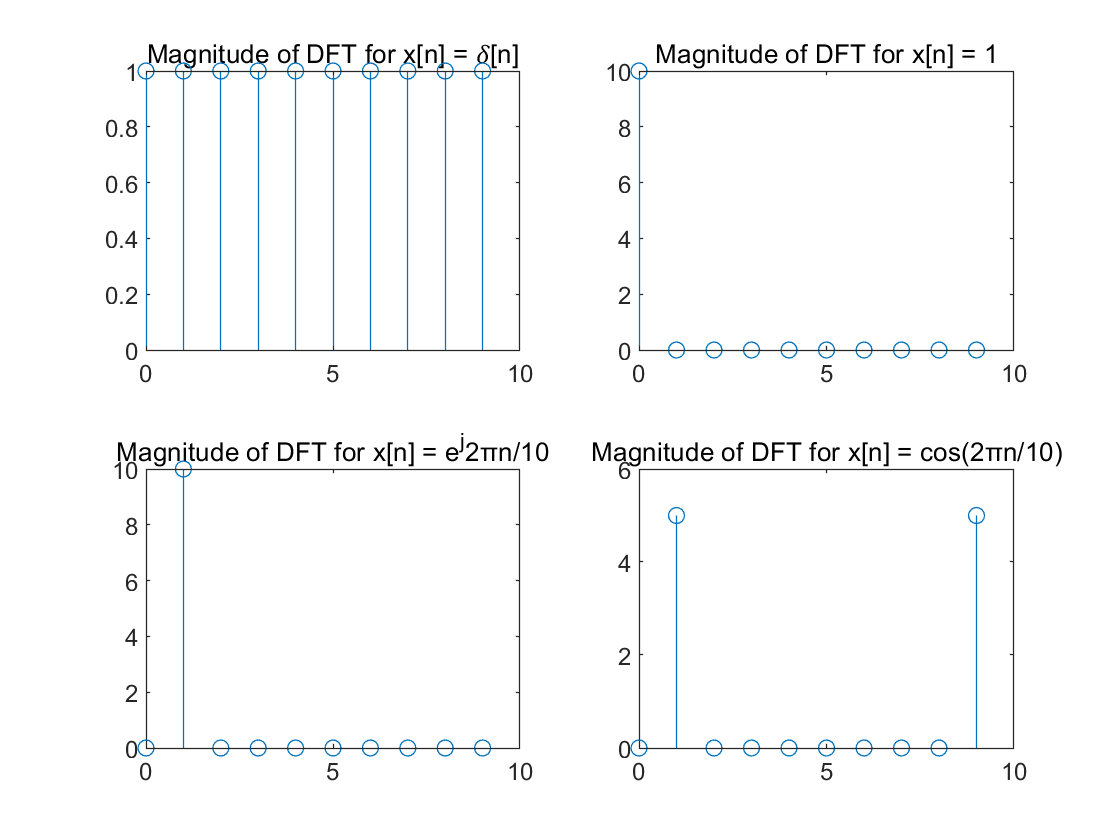


% x[n] = e^j2πn/10
j = sqrt(-1);
x3 = exp(j*2*pi*(0:N-1)/N);
X3 = DFTsum(x3);
subplot(2, 2, 3);
stem(n,abs(X3));
title('Magnitude of DFT for x[n] = e^j2πn/10');

% x[n] = cos(2πn/10)
x4 = cos(2*pi*(0:N-1)/N);
X4 = DFTsum(x4);
subplot(2, 2, 4);
stem(n,abs(X4));
title('Magnitude of DFT for x[n] = cos(2πn/10)');

逆变换

IDFT

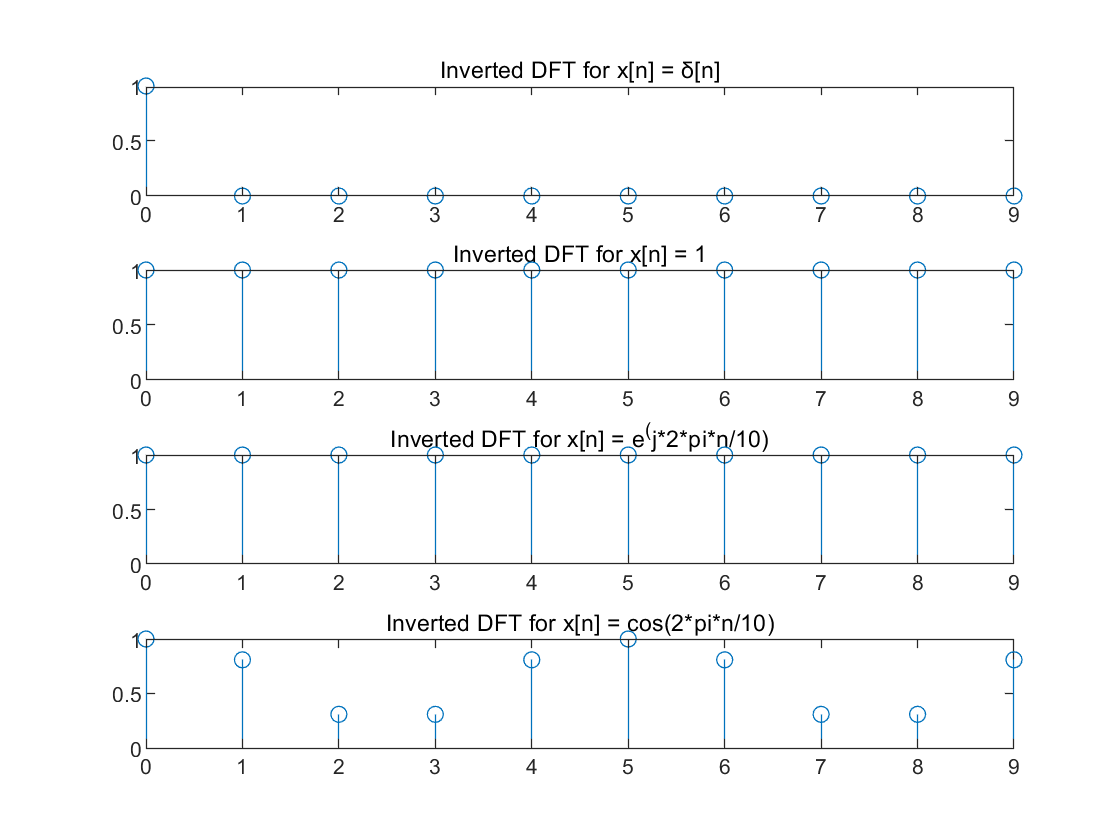


x1_inv = IDFTsum(X1);
x2_inv = IDFTsum(X2);
x3_inv = IDFTsum(X3);
x4_inv = IDFTsum(X4);


figure;
subplot(4,1,1);
stem(n,abs(x1_inv));
title('Inverted DFT for x[n] = δ[n]');

subplot(4,1,2);
stem(n,abs(x2_inv));
title('Inverted DFT for x[n] = 1');

subplot(4,1,3);
stem(n,abs(x3_inv));
title('Inverted DFT for x[n] = e^(j*2*pi*n/10)');

subplot(4,1,4);
stem(n,abs(x4_inv));
title('Inverted DFT for x[n] = cos(2*pi*n/10)');

由于DFT和IDFT是一对互逆变换，所以我们可以验证，通过IDFTsum计算得到的原始信号的幅度图与输入到DFTsum的原始信号的幅度图一致

**4.3.2 Matrix Representation of the DFT**

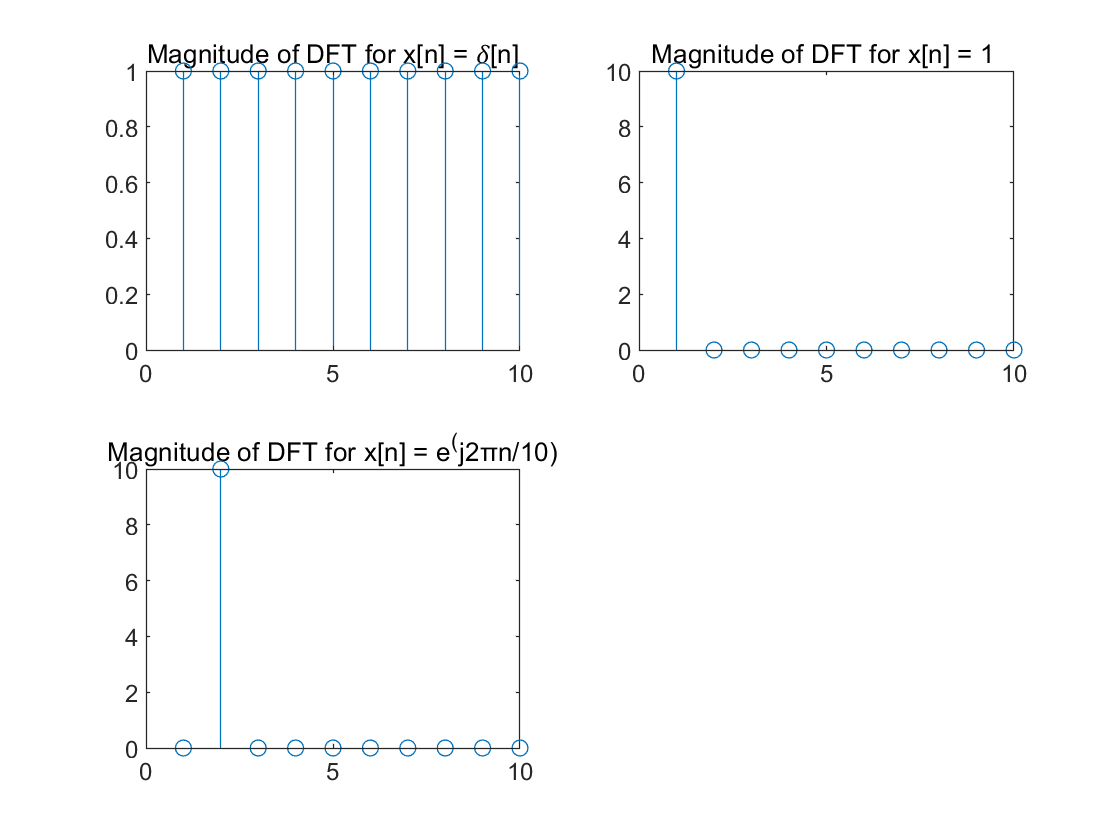

N = 10; 
A = DFTmatrix(N);
figure
% x[n] = 𝛿[n]
x1 = [1 zeros(1, N-1)].';
X1_matrix = A * x1;
subplot(2, 2, 1);
stem(abs(X1_matrix));
title('Magnitude of DFT for x[n] = 𝛿[n]');

%x[n] = 1
x2 = ones(N, 1);
X2_matrix = A * x2;
subplot(2, 2, 2);
stem(abs(X2_matrix));
title('Magnitude of DFT for x[n] = 1 ');

% x[n] = e^j2πn/10
j = sqrt(-1);
x3 = exp(j*2*pi*(0:N-1)/N).';
X3_matrix = A * x3;
subplot(2, 2, 3);
stem(abs(X3_matrix));
title('Magnitude of DFT for x[n] = e^(j2πn/10)');


% N=5时的DFT矩阵A
DFTmatrix(5)

ans =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.3090 - 0.9511i  -0.8090 - 0.5878i  -0.8090 + 0.5878i   0.3090 + 0.9511i
   1.0000 + 0.0000i  -0.8090 - 0.5878i   0.3090 + 0.9511i   0.3090 - 0.9511i  -0.8090 + 0.5878i
   1.0000 + 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i
   1.0000 + 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i


计算N点DFT需要的乘法次数：使用矩阵方法计算N点DFT，其实就是进行一个N x N矩阵与N x 1向量的乘法，这需要N^2次乘法

- 逆DFT矩阵𝐁的：𝐁𝑘𝑛 = 𝑒^𝑗2𝜋(𝑘−1)(𝑛−1)/𝑁，这与DFT矩阵A的元素表达式相似，只是指数的符号变为正。

- 下面是用于生成N x N的逆DFT矩阵B的Matlab函数IDFTmatrix(N)。

N = 5; 
A = DFTmatrix(N); 
B = IDFTmatrix(N);
C = B * A;


disp(B);

   0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i
   0.2000 + 0.0000i   0.0618 + 0.1902i  -0.1618 + 0.1176i  -0.1618 - 0.1176i   0.0618 - 0.1902i
   0.2000 + 0.0000i  -0.1618 + 0.1176i   0.0618 - 0.1902i   0.0618 + 0.1902i  -0.1618 - 0.1176i
   0.2000 + 0.0000i  -0.1618 - 0.1176i   0.0618 + 0.1902i   0.0618 - 0.1902i  -0.1618 + 0.1176i
   0.2000 + 0.0000i   0.0618 - 0.1902i  -0.1618 - 0.1176i  -0.1618 + 0.1176i   0.0618 + 0.1902i



disp(C);

   1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 + 0.0000i



矩阵C是一个单位矩阵，这是因为DFT矩阵A和其逆矩阵B的乘积应该得到单位矩阵，这是线性代数的基本性质。这也验证了我们的DFT矩阵和逆DFT矩阵的计算是正确的。

**4.3.3 Computation Time Comparison **

比较直接使用循环进行DFT和使用矩阵进行DFT

在Matlab中应尽量避免使用循环，而尽可能地使用矩阵/向量乘法。

N = 4096;
x = cos(2*pi*(0:N-1)/10).'; % x[n]
A = DFTmatrix(N);

% 计算DFTsum(x)的CPU时间
start_time = cputime;
X_DFTsum = DFTsum(x);
end_time = cputime;
DFTsum_time = end_time - start_time

DFTsum_time = 3.6250


% 计算A*x的CPU时间
start_time = cputime;
X_matrix = A * x;
end_time = cputime;
matrix_time = end_time - start_time

matrix_time = 0.0625